%% 1. Repàs de la segmentació per watershed

orig = imread('cornea.tif');
figure, imshow(orig)

ee = strel('disk', 1);

% calculem el gradient
grad = imsubtract(imdilate(orig, ee), imerode(orig, ee));
figure, imshow(grad), title('gradient');

% mirem de segmentar les cèlules fent watershed sobre la imatge gradient
segm = watershed(grad);
figure, imshow(segm), title('segmentacio per watershed');

% usarem els màxims regionals com a markers de les cèlules
% la imatge és molt sorollosa. Cal filtrar abans
ee = strel('disk',2);
filt = imopen(imclose(orig, ee), ee); %filtre OC
figure, imshow(filt)
rm = imregionalmax(filt);
figure, imshow(rm), title('maxims regionals')

% Usem els maxims regionals com a markers pel watershed
segm = watershed(imimposemin(grad, rm));
figure, imshow(segm), title('watersehed amb markers')

% Donem un color diferent per cada regió
Lrgb = label2rgb(segm, 'jet','w','shuffle');
figure, imshow(Lrgb)

figure, imshow(orig), hold on, himage = imshow(Lrgb); 
himage.AlphaData = 0.1; 
title('overlay amb color dels contorns obtinguts')
% Cal diferenciar les regions que són cel·lules i les que són fons i
% unificar les regions que són fons

%% Cal trobar un marker pel fons
% L'obtenim fent el watershed de la imatge negada.
% Usem com a markers els mateixos maxims d'abans
Norig = imcomplement(orig);
figure, imshow(Norig), title('imatge negada')
fons = watershed(imimposemin(Norig, rm));
figure, imshow(fons), title('marker del fons')

% Fem una imatge de markers a partir de les celules i del fons
markers =~ fons|rm;
figure, imshow(markers), title('marques')

% fem el watershed amb les noves marques
segm = watershed(imimposemin(grad, markers));
figure, imshow(segm), title('segmentacio final')

% Donem un color diferent per cada regió
Lrgb = label2rgb(segm, 'jet','w','shuffle');
figure, imshow(Lrgb)

figure, imshow(orig), hold on, himage = imshow(Lrgb); 
himage.AlphaData = 0.1; 
title('overlay amb color dels contorns obtinguts')

% fem les marques de les celules més petites per a que no es toquin amb les
% del fons
ee = strel('disk', 2);
rmeroded = imerode(rm, ee);

% tornem a crear la imatge de markers amb els nous markers de les celules
markers =~ fons|rmeroded;
imshow(markers)

% tornem a calcular el wateshed
segm = watershed(imimposemin(grad, markers));
figure, imshow(segm), title('segmentacio final amb noves marques')

% Donem un color diferent per cada regió
Lrgb = label2rgb(segm, 'jet','w','shuffle');
figure, imshow(Lrgb)

figure, imshow(orig), hold on, himage = imshow(Lrgb); 
himage.AlphaData = 0.1; 
title('overlay amb color dels contorns obtinguts')


## 2. Segmentació per clustering. K-means

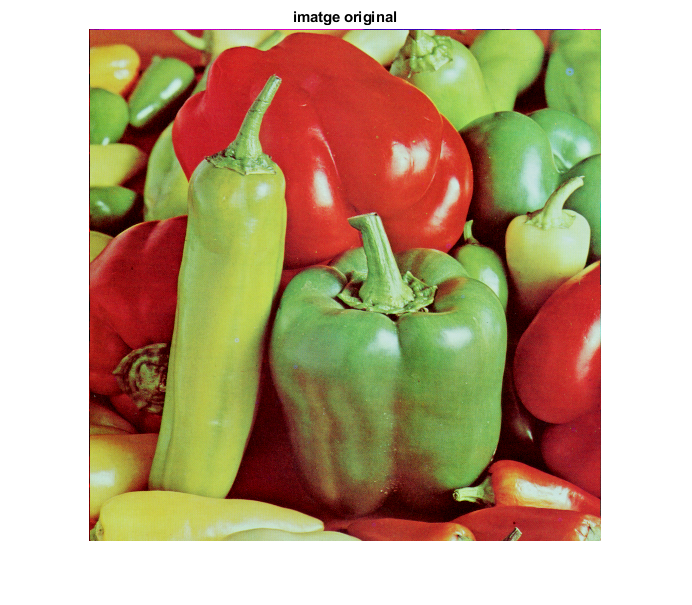

im = imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure, imshow(im), title('imatge original')

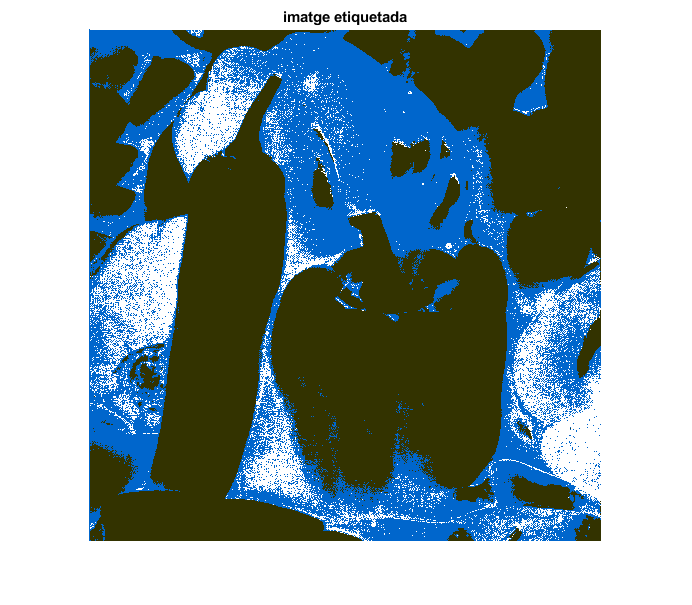


% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv = rgb2hsv(im);
hs = hsv(:,:,1:2);

vect = reshape(hs, MAXFILA*MAXCOL, 2); % feature vector. 2 features per píxel

Nclusters = 3; %vermell, verd, i negre
% Usarem la funció kmeans amb distancia citiblock
[cluster_idx, cluster_center] = kmeans(vect, Nclusters, 'distance','cityblock');

% obtenim la imatge etiquetada pel número cluster
eti = reshape(cluster_idx, MAXFILA, MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

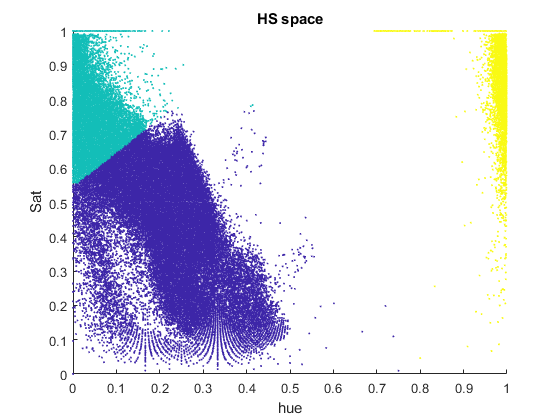


%Algo no va. Els pebrots vermells queden mal segmentats.
% Què està passant?
% Passa que els valors de hue vermells poden estar propers tant al 0 com a
% l'1, ja que representen un angle i el vermell es troba entre els 0º i
% 360º

% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

im = imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure, imshow(im), title('imatge original')


% la segmentarem per color. Treballarem en l’espai Hue-Sat
hsv = rgb2hsv(im);
hs = hsv(:,:,1:2);

vect = reshape(hs, MAXFILA*MAXCOL, 2);

[cluster_idx, cluster_center] = kmeans_angles(vect, 3);

rand_index = 3×2 uint32 matrix
   209734    47671
   113094    69155
   238722    38153


itr = 11

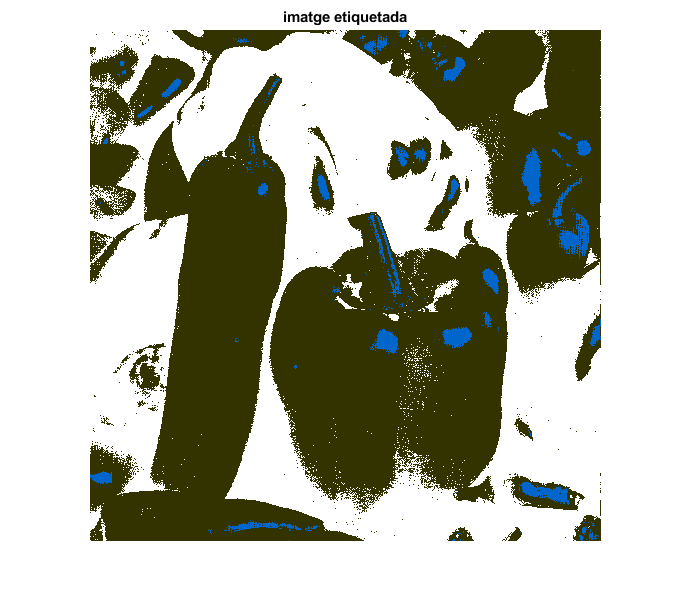

% obtenim la imatge etiquetada pel número cluster
eti = reshape(cluster_idx, MAXFILA, MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

function [cluster_idx, cluster_center] = kmeans_angles(vect, k)
    [n m] = size(vect);
    cluster_idx = zeros(n, 1);
    % Inicialitzem els centres aleatoriament
    rand_nums = rand(k, 2, "double");
    rand_index = uint32(rand_nums * n + 1)
    cluster_center = vect(rand_index);
    
    itr = 0;
    
    while(true)
        itr = itr + 1;
        old_cluster_center = cluster_center;
        
        % per a cada punt
        for i = 1:n
            min_dist = -1;
            min_cluster = 0;
            % per a cada cluster center calculem distancia
            for j = 1:k
                dist_H = vect(i, 1) - old_cluster_center(j, 1);
                if (dist_H > 0.5)
                    dist_H = dist_H - 1;
                elseif (dist_H < -0.5)
                    dist_H = dist_H + 1;
                end
                
                dist_S = vect(i, 2) - old_cluster_center(j, 2);
                
                dist = abs(dist_H) + abs(dist_S);
                
                % indiquem el centre amb distancia minima
                if (min_dist == -1 || dist < min_dist)
                    min_dist = dist;
                    min_cluster = j;
                end
            end
            cluster_idx(i) = min_cluster;
        end
        % recalculem els centres
        for i = 1:k
            index = cluster_idx == i;
            cluster_center(i) = mean(vect(index));
        end
        
        % si l'algoritme convergeix o marcant un número determinat
        % d'iteracions, para
        if (old_cluster_center == cluster_center | itr > 40)
            itr
            break;
        end
    end    
end
